The calculated parameters equation

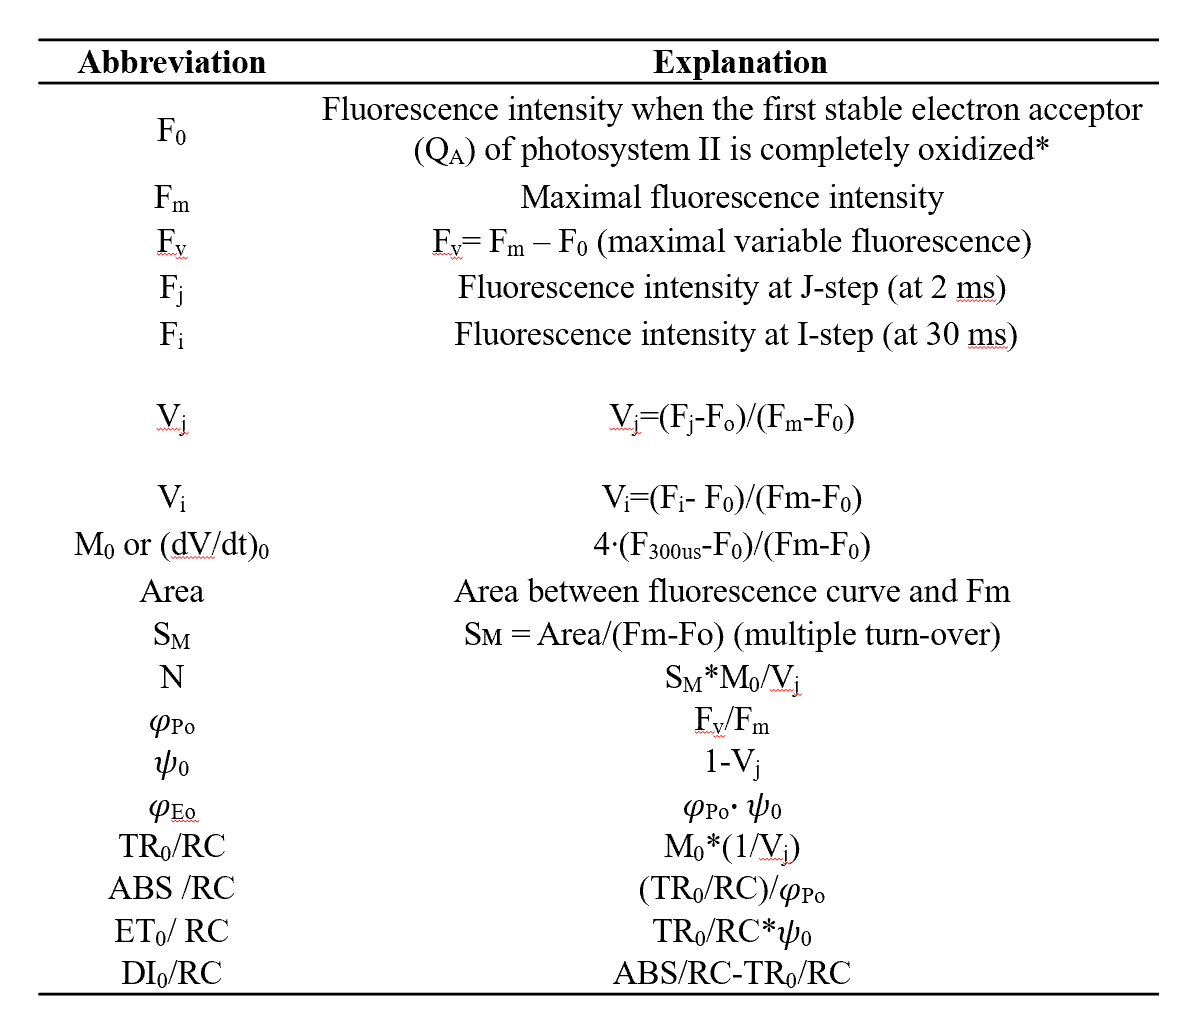

function Para=Calculate_PEA_Para(data)
[samplesize,fluorArry_size]=size(data);
%Para=Calculate_PEA_Para(Data_PEA_Orin_Para)

if fluorArry_size~=119
error('the length of fluorensence is not capmare woth 118');
end

%该版本为不包含0时刻的数据。
load('title_PEA.mat');
Para=zeros(samplesize,18);

for i=1:samplesize
    F0=data(i,1);
    Fm=max(data(i,:));
    Fm_idx=find(data(i,:)==max(data(i,:)));
    Fv=Fm-F0;
    Fj=data(i,48);
    Fi=data(i,85);
    Vj=(Fj-F0)/Fv;
    Vi=(Fi-F0)/Fv;
    M0=4*(data(i,31)-F0)/(Fv);%倍率120%
    Area=calcu_Area(Fm_idx(1),data(i,:),title_PEA);
    Sm=Area/Fv;
    N=Sm*M0/Vj;
    Phi_P0=Fv/Fm;
    Psi_0=1-Vj;
    Phi_Eo=Phi_P0*Psi_0;
    TR0_RC=M0/Vj;
    ABS_RC=TR0_RC/Phi_P0;
    ET0_RC=TR0_RC*Psi_0;
    DI0_RC=ABS_RC-TR0_RC;

    Para(i,1:18)=[F0,Fm,Fv,Fj,Fi,Vj,Vi,M0,Area,Sm,N,Phi_P0,Psi_0,Phi_Eo,TR0_RC,ABS_RC,ET0_RC,DI0_RC];

end

end

%计算面积
function Area=calcu_Area(Fm_idx,data,title_PEA)
Fm=data(Fm_idx(1));
Area=data(1);

for i=2:Fm_idx(1)
    Area=Area+1/2*(title_PEA(i)-title_PEA(i-1))*(2*Fm-data(i)-data(i-1));
    
end

    Area=Area/1000-30000;
end
